# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


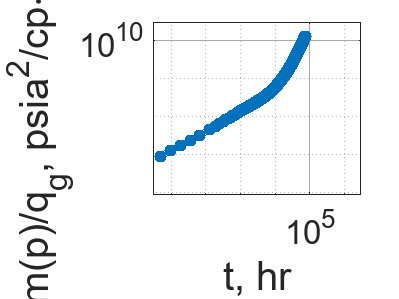


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 201

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_201 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\75%\noisy_data_1.txt", opts)

noisy_RNP_201 = 1150×2 table
       t          RNP    
    _______    __________

       0.25     7.506e+07
    0.33041    9.1891e+07
     0.4862    3.6622e+07
    0.79777    7.2084e+07
     1.4209    4.6953e+06
     2.6672    2.4989e+08
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    2.8241e+07
     35.645    2.3347e+07
      66.06    4.7517e+07
     124.99    2.4188e+08
     188.99    2.9207e+08
     252.99    3.2775e+07
     316.99    1.2669e+08
     380.99      1.64e+08


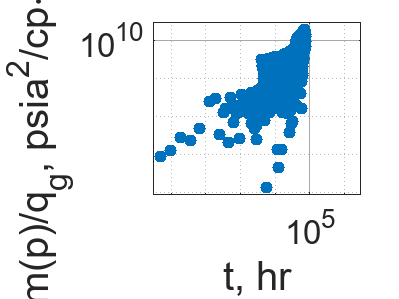


% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 201

logRNP_201 = log(noisy_RNP_201.RNP);

#### Window: 3

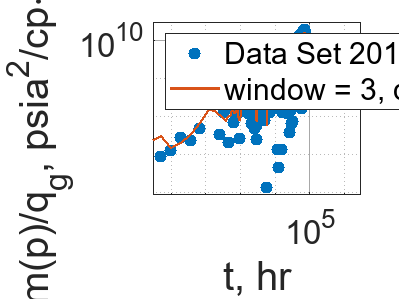

% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 201");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_201_31 = smooth(logRNP_201, 3, "sgolay", 1);
smoothedRNP_201_31 = exp(smoothedLogRNP_201_31);
residual_201_31 = (true_RNP.RNP - smoothedRNP_201_31) ./ (0.3413 .* true_RNP.RNP);
sse_201_31 = sum(residual_201_31 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

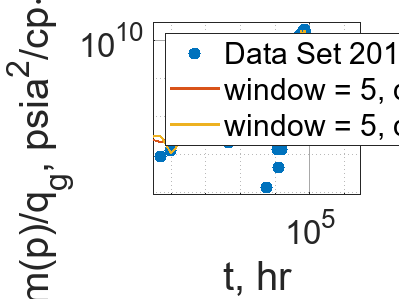

% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 201");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_201_51 = smooth(logRNP_201, 5, "sgolay", 1);
smoothedRNP_201_51 = exp(smoothedLogRNP_201_51);
residual_201_51 = (true_RNP.RNP - smoothedRNP_201_51) ./ (0.3413 .* true_RNP.RNP);
sse_201_51 = sum(residual_201_51 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_201_52 = smooth(logRNP_201, 5, "sgolay", 2);
smoothedRNP_201_52 = exp(smoothedLogRNP_201_52);
residual_201_52 = (true_RNP.RNP - smoothedRNP_201_52) ./ (0.3413 .* true_RNP.RNP);
sse_201_52 = sum(residual_201_52 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

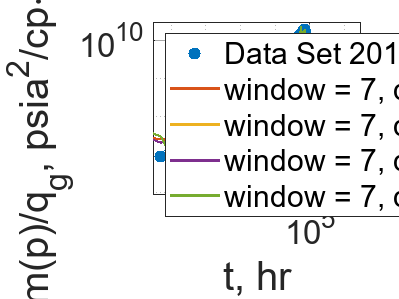

% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 201");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_201_71 = smooth(logRNP_201, 7, "sgolay", 1);
smoothedRNP_201_71 = exp(smoothedLogRNP_201_71);
residual_201_71 = (true_RNP.RNP - smoothedRNP_201_71) ./ (0.3413 .* true_RNP.RNP);
sse_201_71 = sum(residual_201_71 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_201_72 = smooth(logRNP_201, 7, "sgolay", 2);
smoothedRNP_201_72 = exp(smoothedLogRNP_201_72);
residual_201_72 = (true_RNP.RNP - smoothedRNP_201_72) ./ (0.3413 .* true_RNP.RNP);
sse_201_72 = sum(residual_201_72 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_201_73 = smooth(logRNP_201, 7, "sgolay", 3);
smoothedRNP_201_73 = exp(smoothedLogRNP_201_73);
residual_201_73 = (true_RNP.RNP - smoothedRNP_201_73) ./ (0.3413 .* true_RNP.RNP);
sse_201_73 = sum(residual_201_73 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_201_74 = smooth(logRNP_201, 7, "sgolay", 4);
smoothedRNP_201_74 = exp(smoothedLogRNP_201_74);
residual_201_74 = (true_RNP.RNP - smoothedRNP_201_74) ./ (0.3413 .* true_RNP.RNP);
sse_201_74 = sum(residual_201_74 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

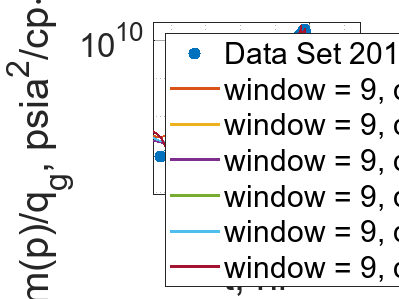

% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 201");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_201_91 = smooth(logRNP_201, 9, "sgolay", 1);
smoothedRNP_201_91 = exp(smoothedLogRNP_201_91);
residual_201_91 = (true_RNP.RNP - smoothedRNP_201_91) ./ (0.3413 .* true_RNP.RNP);
sse_201_91 = sum(residual_201_91 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_201_92 = smooth(logRNP_201, 9, "sgolay", 2);
smoothedRNP_201_92 = exp(smoothedLogRNP_201_92);
residual_201_92 = (true_RNP.RNP - smoothedRNP_201_92) ./ (0.3413 .* true_RNP.RNP);
sse_201_92 = sum(residual_201_92 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_201_93 = smooth(logRNP_201, 9, "sgolay", 3);
smoothedRNP_201_93 = exp(smoothedLogRNP_201_93);
residual_201_93 = (true_RNP.RNP - smoothedRNP_201_93) ./ (0.3413 .* true_RNP.RNP);
sse_201_93 = sum(residual_201_93 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_201_94 = smooth(logRNP_201, 9, "sgolay", 4);
smoothedRNP_201_94 = exp(smoothedLogRNP_201_94);
residual_201_94 = (true_RNP.RNP - smoothedRNP_201_94) ./ (0.3413 .* true_RNP.RNP);
sse_201_94 = sum(residual_201_94 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_201_95 = smooth(logRNP_201, 9, "sgolay", 5);
smoothedRNP_201_95 = exp(smoothedLogRNP_201_95);
residual_201_95 = (true_RNP.RNP - smoothedRNP_201_95) ./ (0.3413 .* true_RNP.RNP);
sse_201_95 = sum(residual_201_95 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_201_96 = smooth(logRNP_201, 9, "sgolay", 6);
smoothedRNP_201_96 = exp(smoothedLogRNP_201_96);
residual_201_96 = (true_RNP.RNP - smoothedRNP_201_96) ./ (0.3413 .* true_RNP.RNP);
sse_201_96 = sum(residual_201_96 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

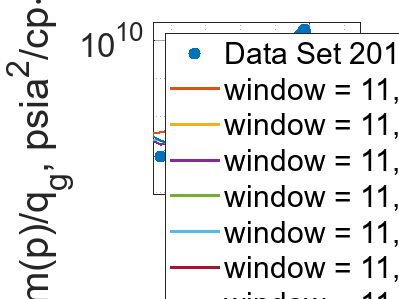

% Plot
loglog(noisy_RNP_201.t, noisy_RNP_201.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 201");
% title("Noisy RNP Data Set 201", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_201_111 = smooth(logRNP_201, 11, "sgolay", 1);
smoothedRNP_201_111 = exp(smoothedLogRNP_201_111);
residual_201_111 = (true_RNP.RNP - smoothedRNP_201_111) ./ (0.3413 .* true_RNP.RNP);
sse_201_111 = sum(residual_201_111 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_201_112 = smooth(logRNP_201, 11, "sgolay", 2);
smoothedRNP_201_112 = exp(smoothedLogRNP_201_112);
residual_201_112 = (true_RNP.RNP - smoothedRNP_201_112) ./ (0.3413 .* true_RNP.RNP);
sse_201_112 = sum(residual_201_112 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_201_113 = smooth(logRNP_201, 11, "sgolay", 3);
smoothedRNP_201_113 = exp(smoothedLogRNP_201_113);
residual_201_113 = (true_RNP.RNP - smoothedRNP_201_113) ./ (0.3413 .* true_RNP.RNP);
sse_201_113 = sum(residual_201_113 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_201_114 = smooth(logRNP_201, 11, "sgolay", 4);
smoothedRNP_201_114 = exp(smoothedLogRNP_201_114);
residual_201_114 = (true_RNP.RNP - smoothedRNP_201_114) ./ (0.3413 .* true_RNP.RNP);
sse_201_114 = sum(residual_201_114 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_201_115 = smooth(logRNP_201, 11, "sgolay", 5);
smoothedRNP_201_115 = exp(smoothedLogRNP_201_115);
residual_201_115 = (true_RNP.RNP - smoothedRNP_201_115) ./ (0.3413 .* true_RNP.RNP);
sse_201_115 = sum(residual_201_115 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_201_116 = smooth(logRNP_201, 11, "sgolay", 6);
smoothedRNP_201_116 = exp(smoothedLogRNP_201_116);
residual_201_116 = (true_RNP.RNP - smoothedRNP_201_116) ./ (0.3413 .* true_RNP.RNP);
sse_201_116 = sum(residual_201_116 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_201_117 = smooth(logRNP_201, 11, "sgolay", 7);
smoothedRNP_201_117 = exp(smoothedLogRNP_201_117);
residual_201_117 = (true_RNP.RNP - smoothedRNP_201_117) ./ (0.3413 .* true_RNP.RNP);
sse_201_117 = sum(residual_201_117 .^ 2);
loglog(noisy_RNP_201.t, smoothedRNP_201_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;